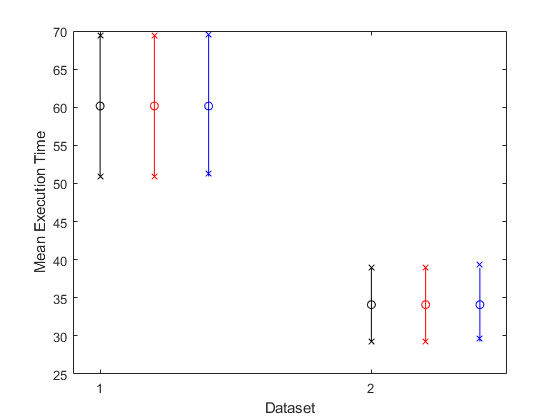

clear all;
close all;

fin = fopen('sgbdold.dat','r');
data = fscanf(fin,'%f');
fclose(fin);
sample_mean = mean(data);
sample_std = std(data);
eta = 1.96;
lb1 = sample_mean - eta*sample_std/sqrt(length(data));
ub1 = sample_mean + eta*sample_std/sqrt(length(data));

sample_std = sqrt(sum((data-sample_mean).^2)/length(data));
lb2 = sample_mean - eta*sample_std/sqrt(length(data));
ub2 = sample_mean + eta*sample_std/sqrt(length(data));

ci = bootci(10000,@mean,data);
lb3 = ci(1);
ub3 = ci(2);

plot(1,sample_mean,'ok');
hold on
plot(lb1,'xk');
hold on
plot(ub1,'xk');
hold on
plot(1.2,sample_mean,'or');
hold on
plot(1.2,lb2,'xr');
hold on
plot(1.2,ub2,'xr');
hold on
plot(1.4,sample_mean,'ob');
hold on
plot(1.4,lb3,'xb');
hold on
plot(1.4,ub3,'xb');
hold on
plot([1,1],[lb1,ub1],'k');
hold on
plot([1.2,1.2],[lb1,ub1],'r');
hold on
plot([1.4,1.4],[lb1,ub1],'b');
hold on

fin = fopen('sgbdnew.dat','r');
data = fscanf(fin,'%f');
fclose(fin);
sample_mean = mean(data);
sample_std = std(data);
eta = 1.96;
lb1 = sample_mean - eta*sample_std/sqrt(length(data));
ub1 = sample_mean + eta*sample_std/sqrt(length(data));

sample_std = sqrt(sum((data-sample_mean).^2)/length(data));
lb2 = sample_mean - eta*sample_std/sqrt(length(data));
ub2 = sample_mean + eta*sample_std/sqrt(length(data));

ci = bootci(10000,@mean,data);
lb3 = ci(1);
ub3 = ci(2);

plot(2,sample_mean,'ok');
hold on
plot(2,lb1,'xk');
hold on
plot(2,ub1,'xk');
hold on
plot(2.2,sample_mean,'or');
hold on
plot(2.2,lb2,'xr');
hold on
plot(2.2,ub2,'xr');
hold on
plot(2.4,sample_mean,'ob');
hold on
plot(2.4,lb3,'xb');
hold on
plot(2.4,ub3,'xb');
hold on
plot([2,2],[lb1,ub1],'k');
hold on
plot([2.2,2.2],[lb1,ub1],'r');
hold on
plot([2.4,2.4],[lb1,ub1],'b');
xticks([1 2]);
xlabel('Dataset');
ylabel('Mean Execution Time');
xlim([0.9 2.5]);